# Independent Component Analysis of whole brain using Aya's EEG dataset: Similarity Analysis

clear;

% ===============================================
% Compute ICA for each subject × condition × subtype
% ===============================================

clear; clc;

%% 1) Set your input/output roots
if exist('H:\', 'dir')         % Computer 1
    input_root  = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
    output_root = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
elseif exist('G:\', 'dir')     % Computer 2
    input_root  = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
    output_root = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
else
    error('Unknown system. Please adjust your paths.');
end

conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'

% Start the parallel pool once at the beginning
try
    poolobj = gcp('nocreate'); % Get current parallel pool without creating one
    if isempty(poolobj)
        poolobj = parpool(); % Create a parallel pool with default settings
    end
catch err
    warning('Could not create parallel pool');
    warning('Running in serial mode instead');
end

for j = 1:length(subjects)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


    subject = subjects{j};
    match_ICs_cosine_euclidean(subject, input_root);

end

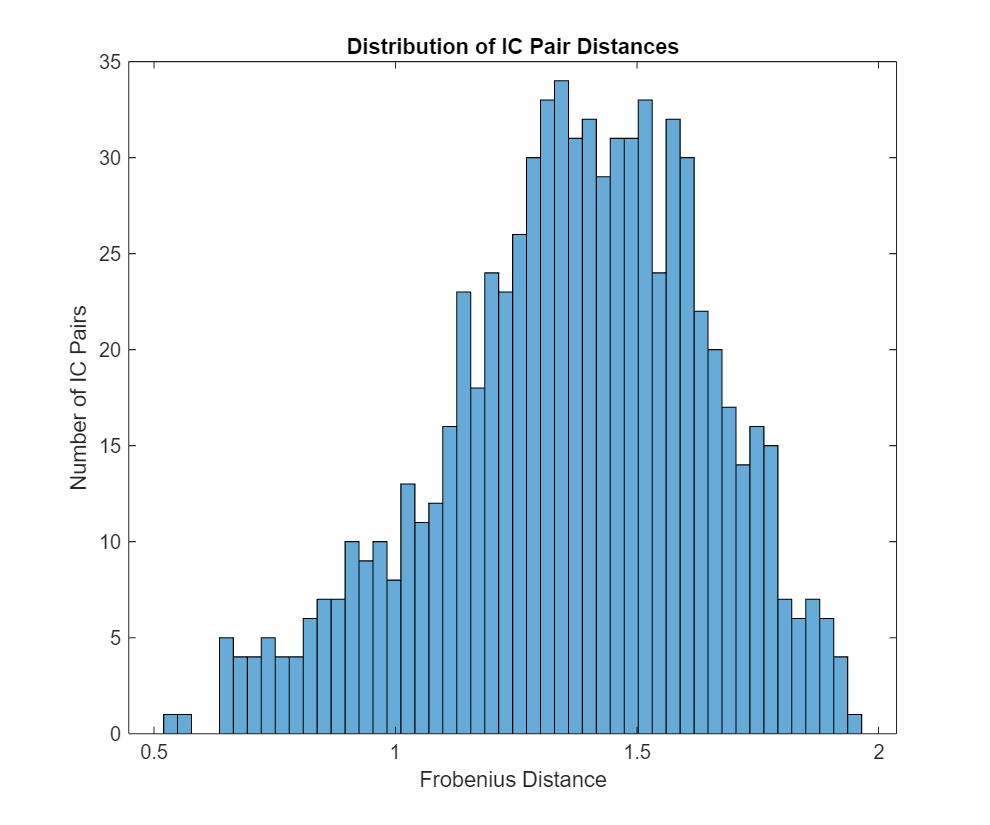

  • 0 IC pairs matched with Frobenius distance < 0.30


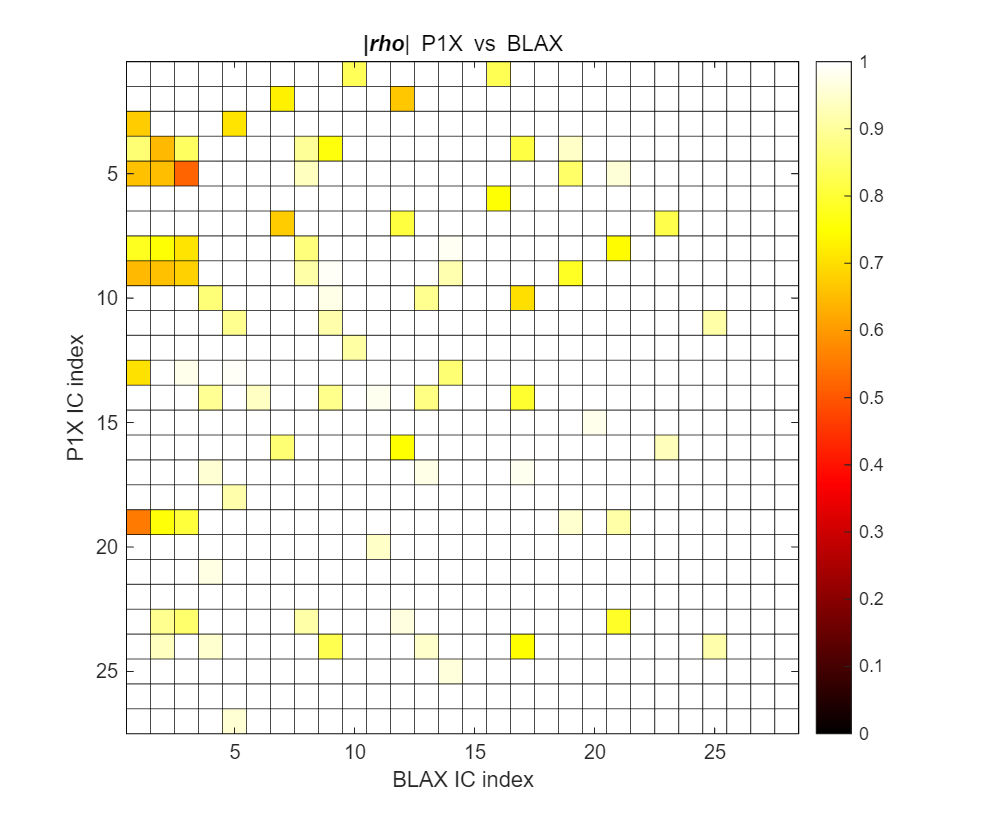

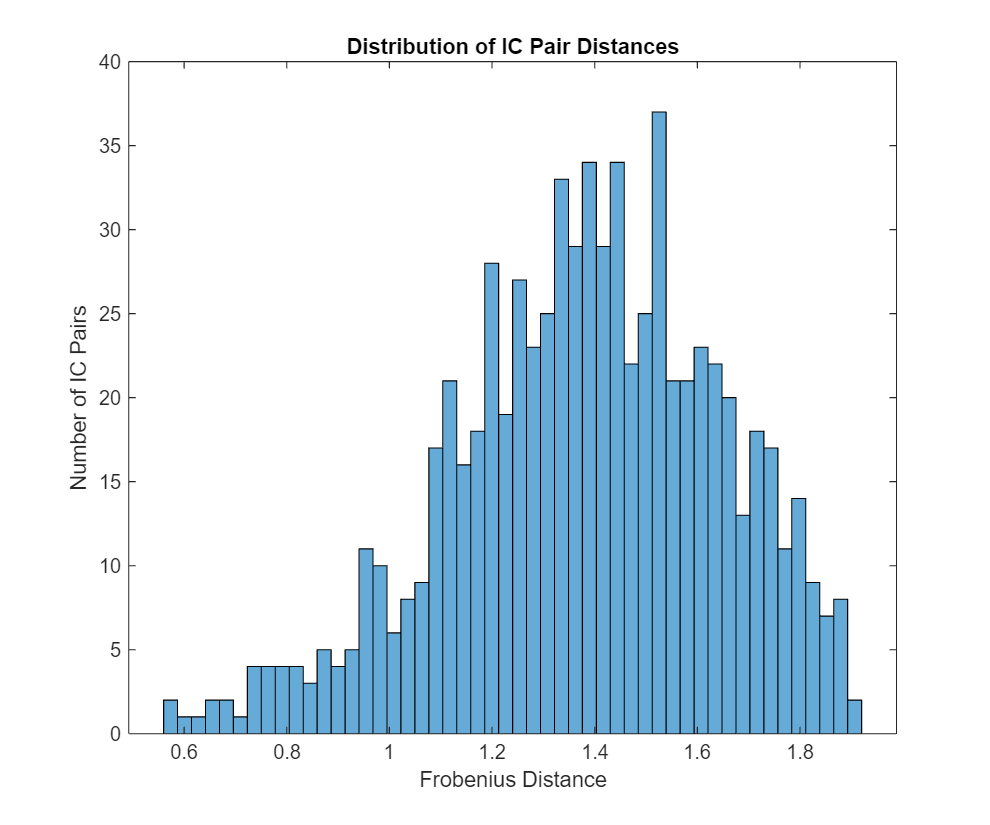

  • 0 IC pairs matched with Frobenius distance < 0.30


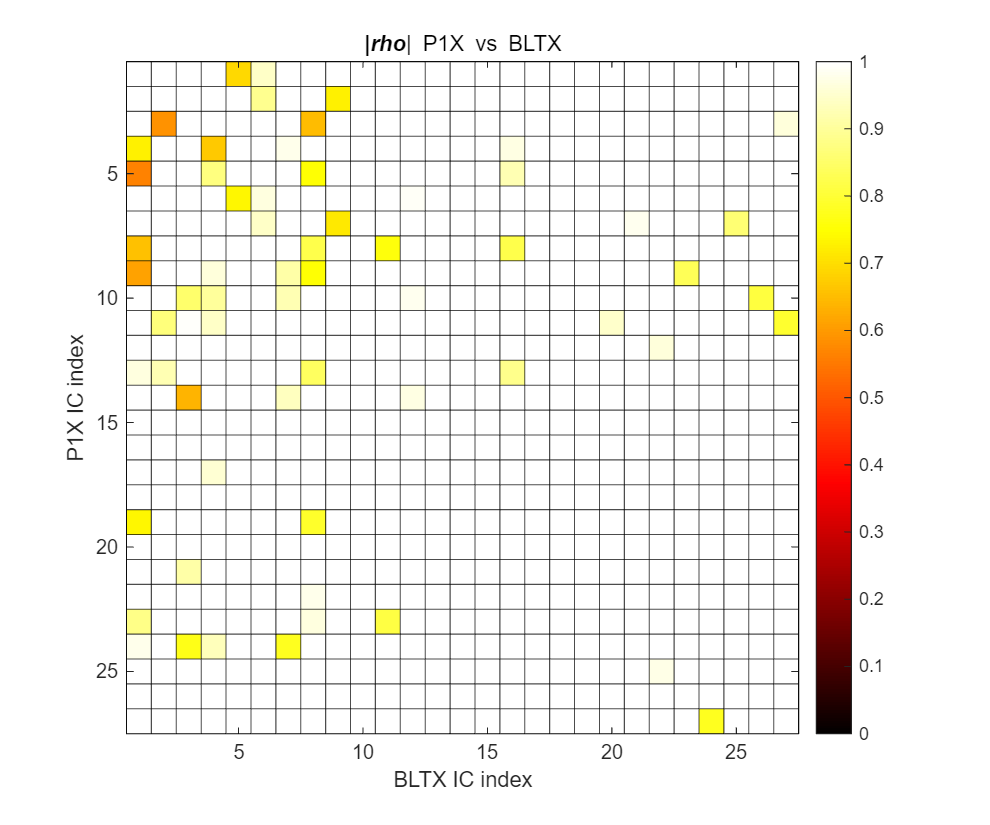

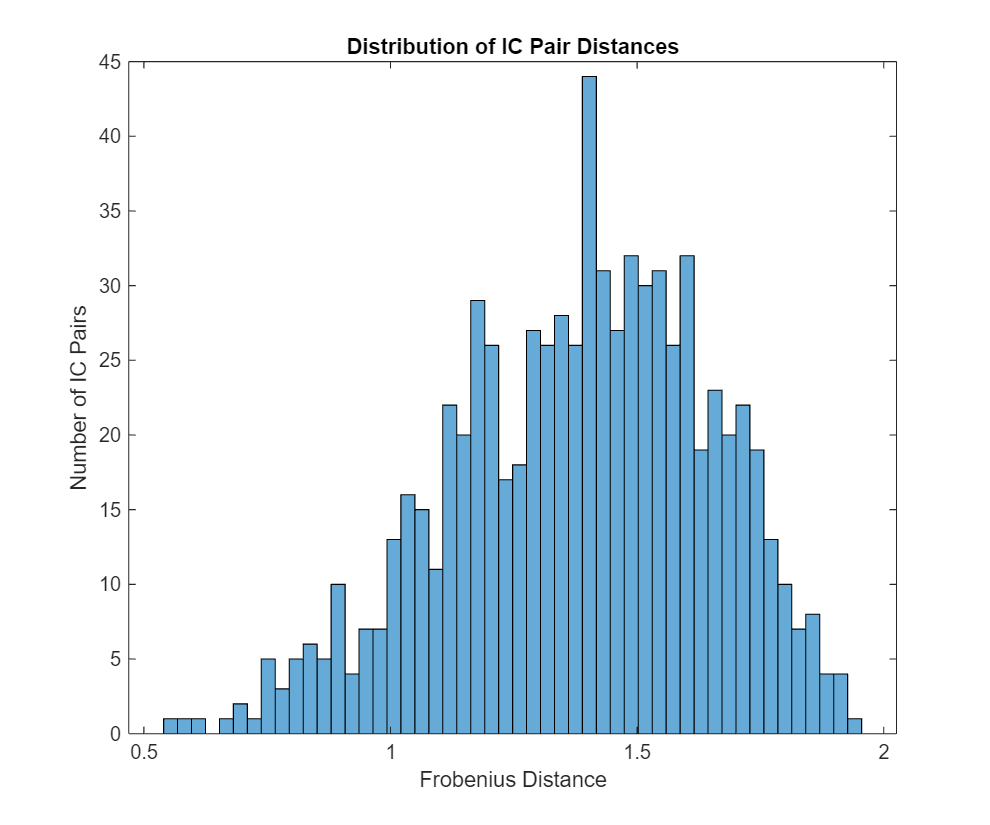

  • 0 IC pairs matched with Frobenius distance < 0.30


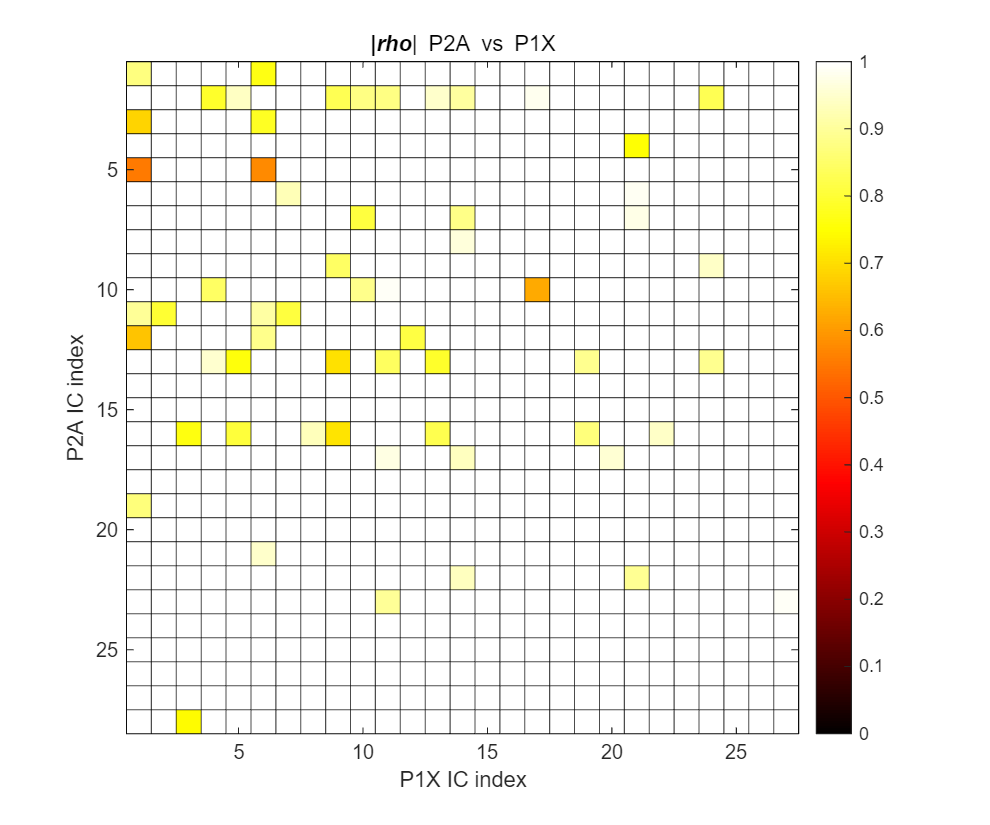

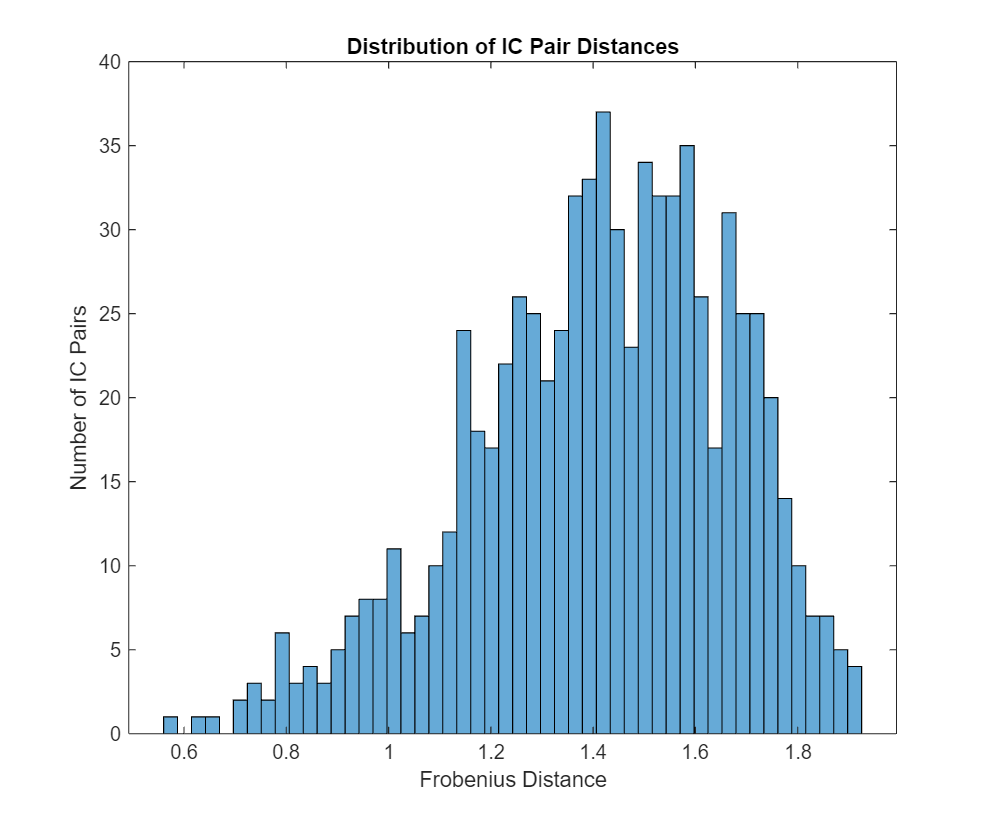

  • 0 IC pairs matched with Frobenius distance < 0.30


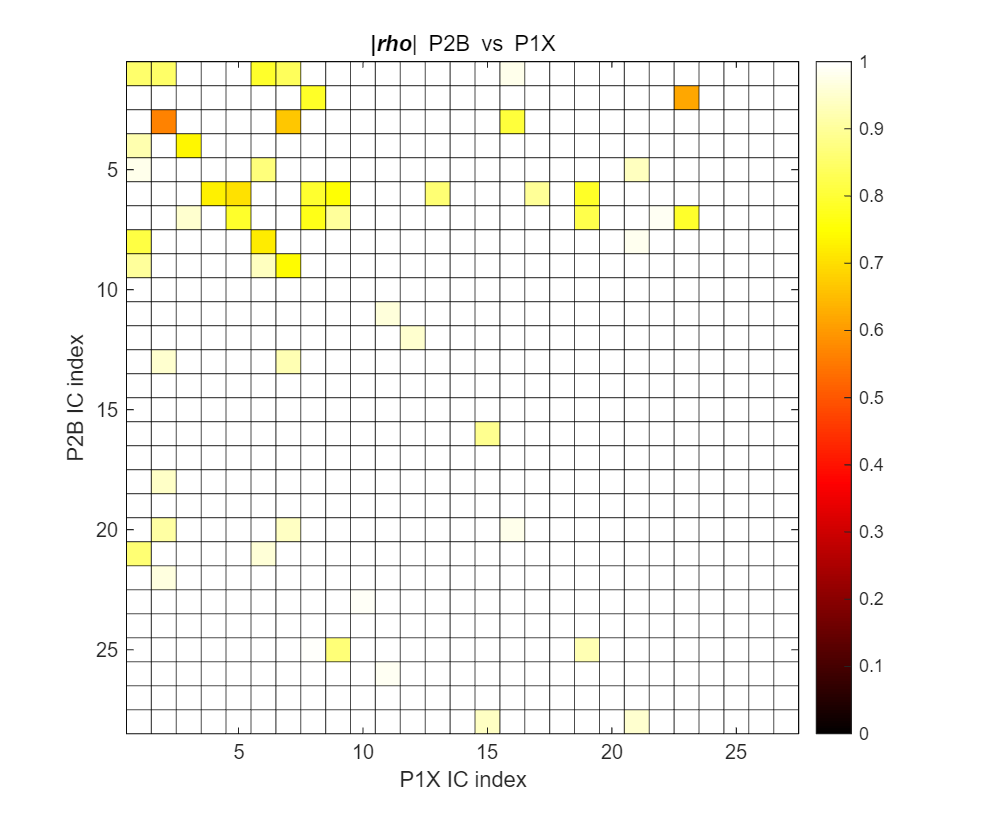

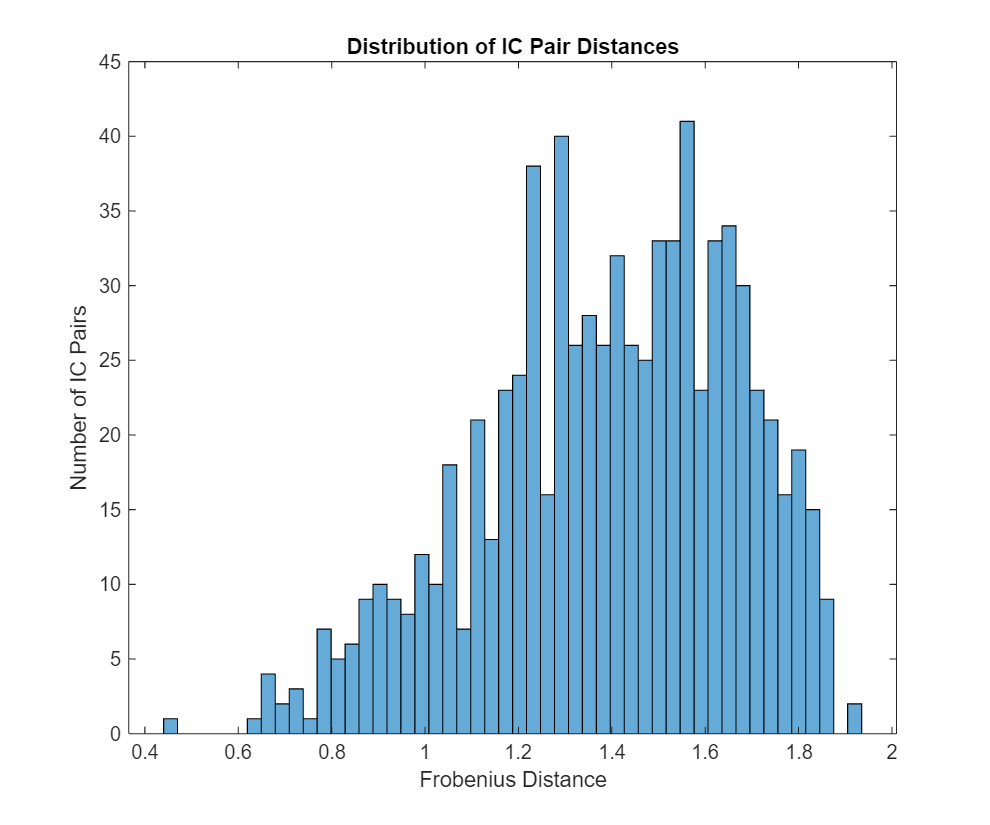

  • 0 IC pairs matched with Frobenius distance < 0.30


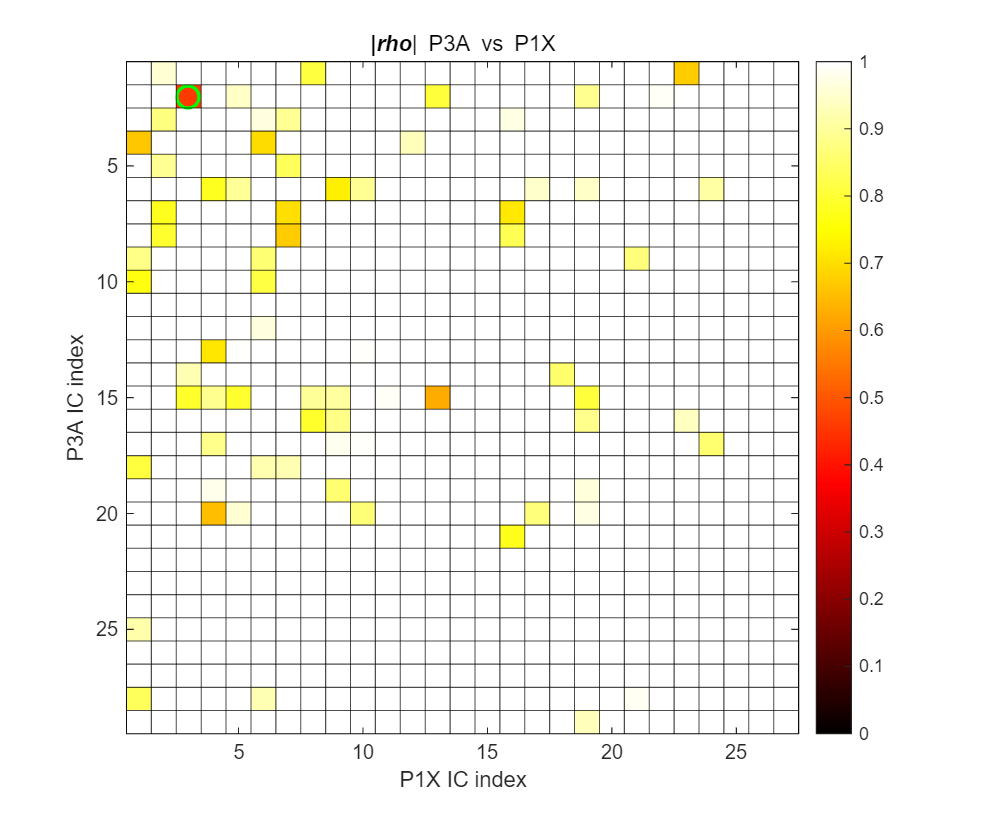

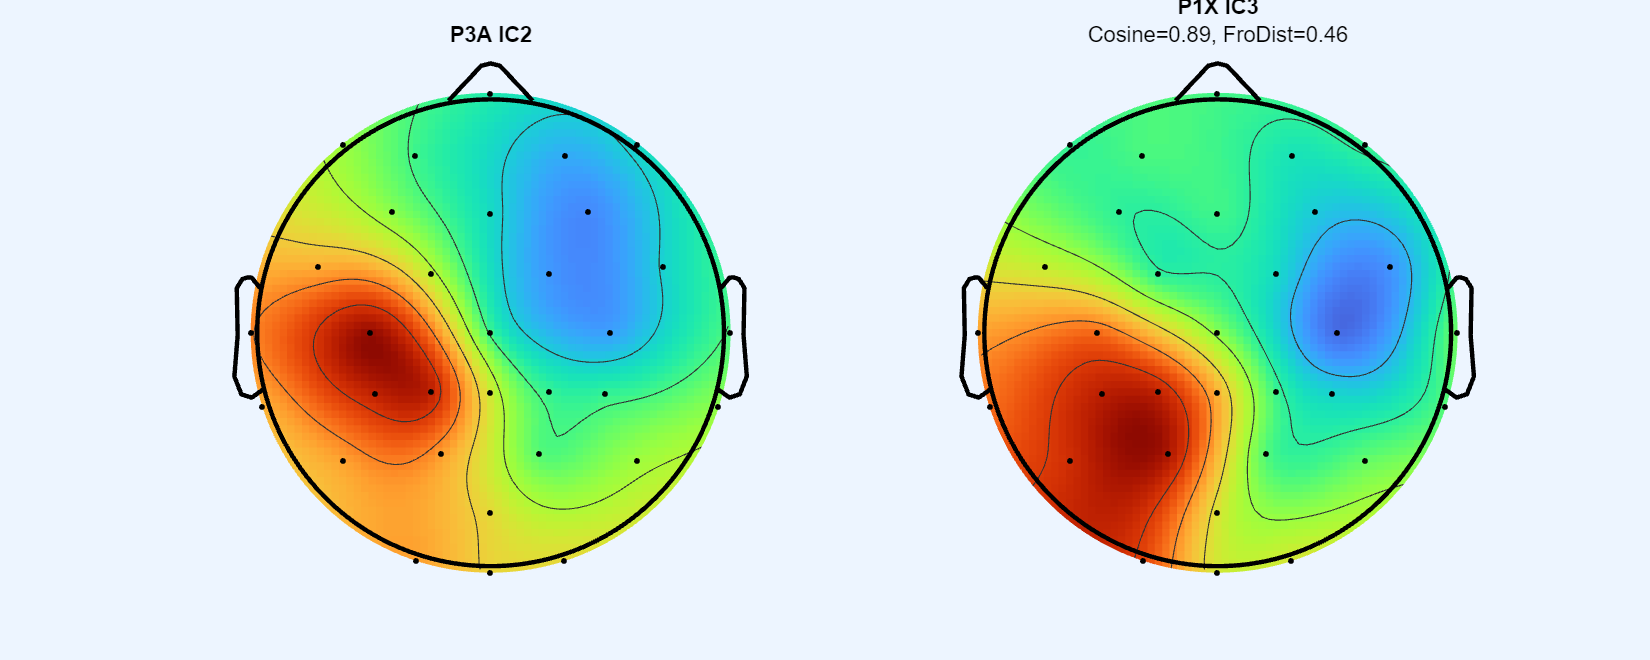

  • 0 IC pairs matched with Frobenius distance < 0.30


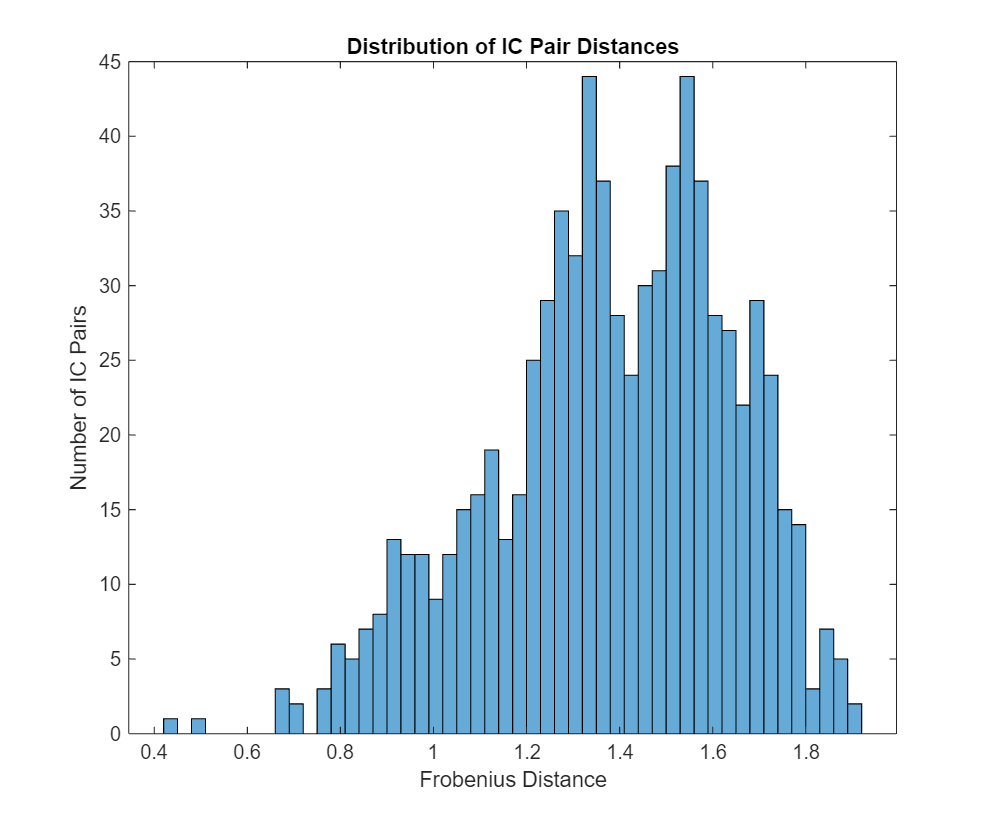

  • 2 IC pairs matched with Frobenius distance < 0.50


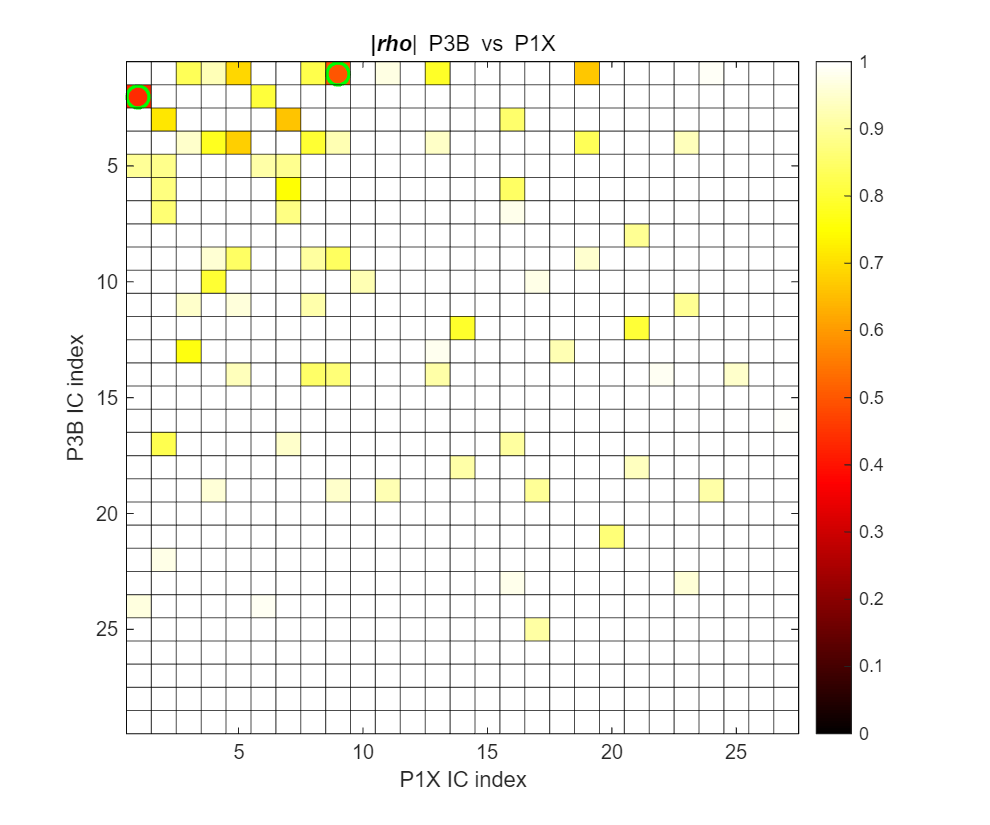

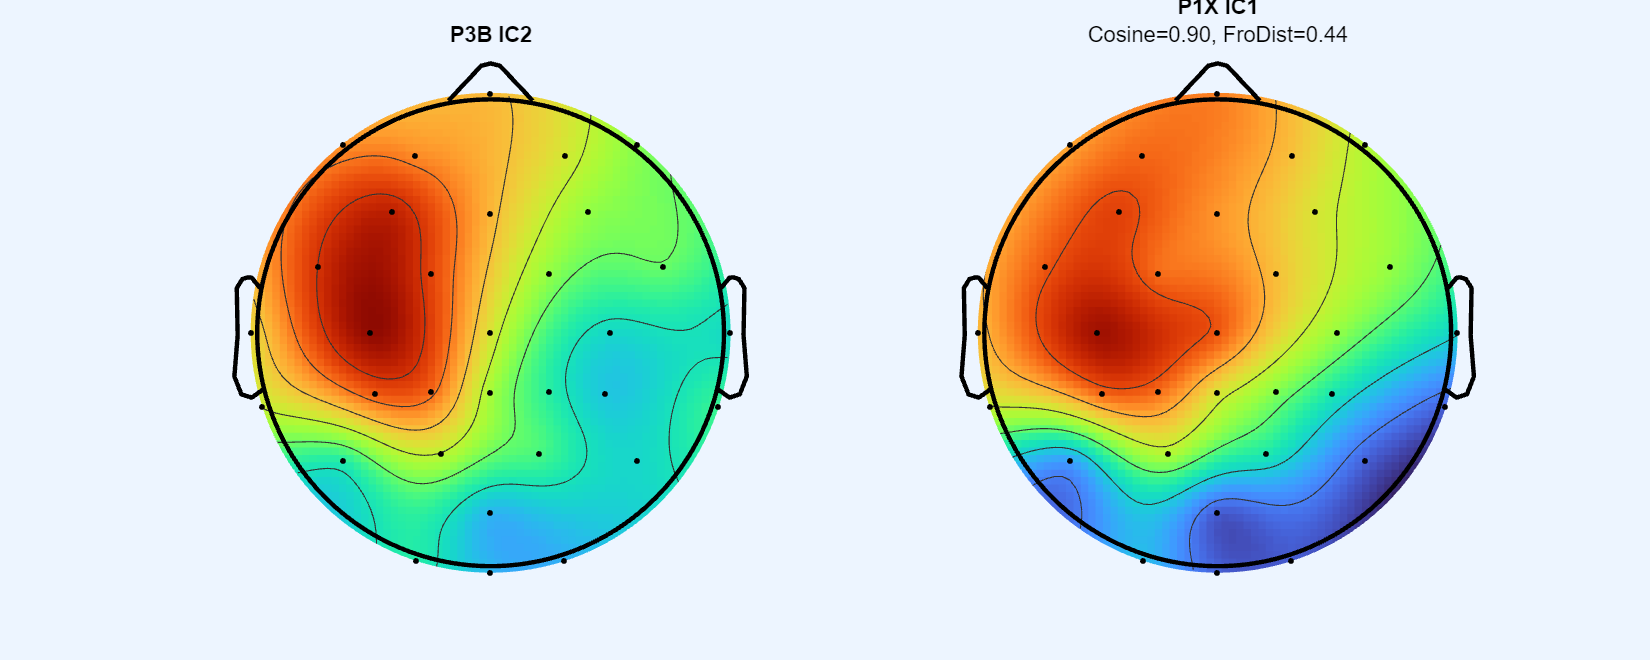

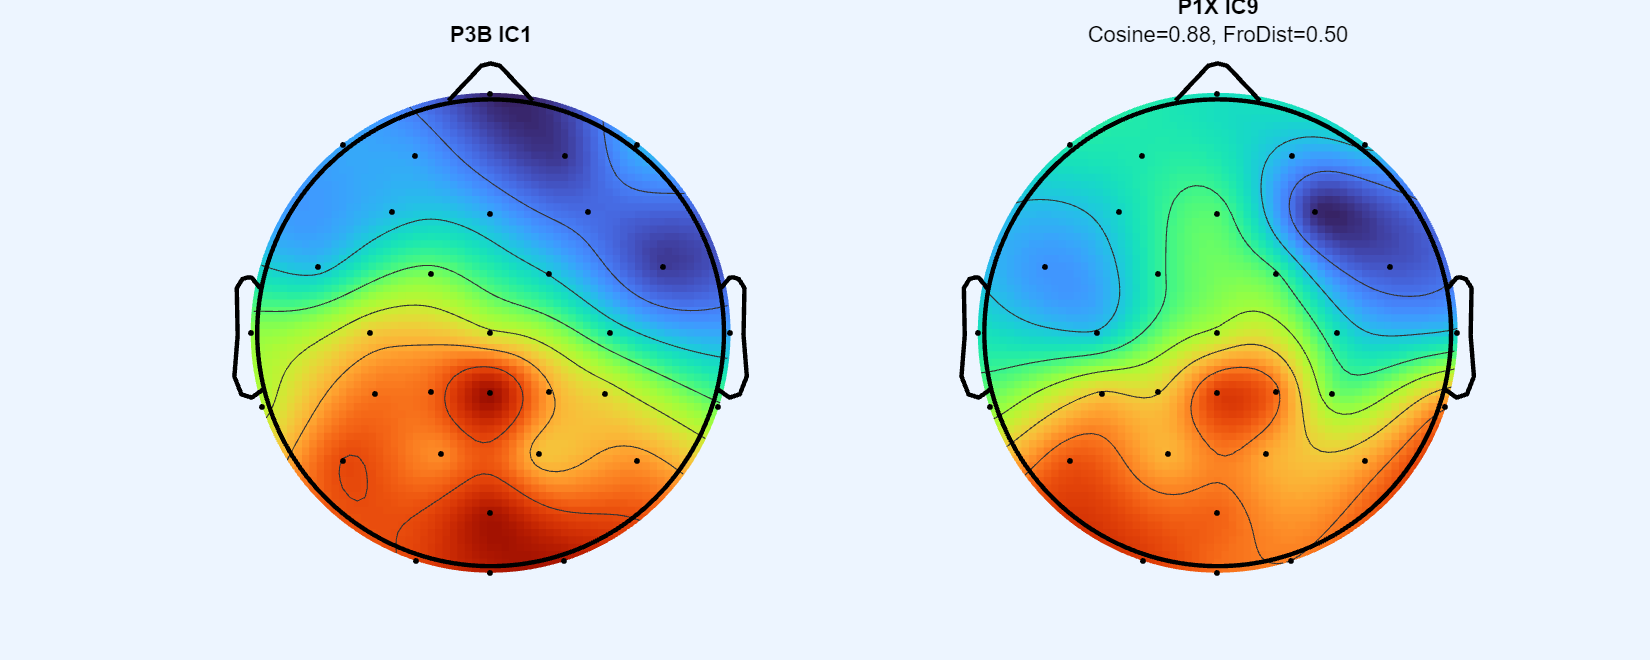

function match_ICs_cosine_euclidean(subject, input_root)

% MATCH_ICS_ACROSS_CONDITIONS  Correlate ICA scalp maps across your conditions
%
%   match_ICs_across_conditions('BOS2', ...
%        'C:\…\temporal_criticality_of_latent_results\ICA\')
%
%   Assumes you have saved each condition/subtag’s EEGsub in:
%     input_root\<subject>\<condition>\<subtag>\EEG_ICA.mat

  %% 1) Define which pairs to compare
  comparisons = { ...
    {'P1','X', 'BLA','X'};    % P1 vs BLA
    {'P1','X', 'BLT','X'};    % P1 vs BLT
    {'P2','A', 'P1','X'};     % P2A vs P1
    {'P2','B', 'P1','X'};     % P2B vs P1
    {'P3','A', 'P1','X'};     % P3A vs P1
    {'P3','B', 'P1','X'};     % P3B vs P1
  };

  for k = 1:numel(comparisons)
    C = comparisons{k};
    cond1 = C{1}; sub1 = C{2};
    cond2 = C{3}; sub2 = C{4};

    % Build paths
    p1 = fullfile(input_root, subject, cond1, sub1, 'EEG_ICA.mat');
    p2 = fullfile(input_root, subject, cond2, sub2, 'EEG_ICA.mat');
    if ~exist(p1,'file') || ~exist(p2,'file')
      warning('Missing %s or %s — skipping', p1, p2);
      continue;
    end

    % Load
    tmp = load(p1,'EEGsub'); EEG1 = tmp.EEGsub;  clear tmp;
    tmp = load(p2,'EEGsub'); EEG2 = tmp.EEGsub;  clear tmp;

    % Extract mixing matrices
    A1 = EEG1.icawinv;   % [nCh × nIC1]
    A2 = EEG2.icawinv;   % [nCh × nIC2]
    nIC1 = size(A1,2);
    nIC2 = size(A2,2);
    
    % Normalize IC topographies
    A1_norm =  A1 ./ vecnorm(A1);
    A2_norm =  A2 ./ vecnorm(A2);

    % Compute Cosine similarity matrix
    cosSimMat = abs(A1_norm' * A2_norm);

    %% 2) Compute Euclidean distance matrix
    distMat = zeros(nIC1,nIC2);
    for i = 1:nIC1
      for j = 1:nIC2
        d1 = norm(A1(:,i) - A2(:,j));    % Distance without flip
        d2 = norm(A1(:,i) + A2(:,j));    % Distance with sign flip
        distMat(i,j) = min(d1, d2);      % Sign-invariant distance
      end
    end
    
    %% 2.2) Finding the threshold
    figure('Name',sprintf('%s: %s%s vs %s%s',subject,cond1,sub1,cond2,sub2),...
           'NumberTitle','off','Position',[100 100 600 500]);
    histogram(distMat(:), 50);
    xlabel('Frobenius Distance');
    ylabel('Number of IC Pairs');
    title('Distribution of IC Pair Distances');


    %% 3) Threshold & (optional) one-to-one matching
    distThresh = 0.3; % perhaps need to also include inverted IC with distance > 1.41
    [I,J] = find(distMat < distThresh);

    % === Print report ===
    fprintf('  • %d IC pairs matched with Frobenius distance < %.2f\n', numel(I), distThresh);

    %% 4) Plot
    figure('Name',sprintf('%s: %s%s vs %s%s',subject,cond1,sub1,cond2,sub2),...
           'NumberTitle','off','Position',[100 100 600 500]);
    imagesc(distMat, [0 1]);
    axis tight; axis square;
    xlabel(sprintf('%s%s IC index',cond2,sub2));
    ylabel(sprintf('%s%s IC index',cond1,sub1));
    title(sprintf('|\\itrho\\rm| %s%s vs %s%s', cond1,sub1, cond2,sub2));
    colorbar; colormap('hot');

    hold on;
    % mark all pairs above threshold
    plot(J, I, 'go', 'MarkerSize',10, 'LineWidth',1.5);

    % (optional) mark one-to-one matches in a different color:
    % for p = 1:size(pairs,1)
    %   plot(pairs(p,2), pairs(p,1), 'bx', 'MarkerSize',12, 'LineWidth',2);
    % end

    % Draw threshold lines
    yline(0.5 + (0:nIC1),'k-','LineWidth',0.5);
    xline(0.5 + (0:nIC2),'k-','LineWidth',0.5);

    hold off;

    % Save figure
    outfig = fullfile(input_root, subject, ...
                      sprintf('match_%s%s_vs_%s%s.png', ...
                              cond1,sub1,cond2,sub2));
    saveas(gcf, outfig);
    % close(gcf);
    
    % === Visualize matched ICs topographically ===
    % Requires EEGLAB's topoplot function
    for idx = 1:length(I)
        ic1 = I(idx);
        ic2 = J(idx);
    
        figure('Name', sprintf('Match %d: %s%s IC%d vs %s%s IC%d', ...
            idx, cond1, sub1, ic1, cond2, sub2, ic2), ...
            'NumberTitle', 'off', 'Position', [200 200 1000 500]);
    
        subplot(1,2,1);
        topoplot(A1(:,ic1), EEG1.chanlocs);  % assumes EEG1 has chanlocs
        title(sprintf('%s%s IC%d', cond1, sub1, ic1));
    
        subplot(1,2,2);
        topoplot(A2(:,ic2), EEG2.chanlocs);
        title(sprintf('%s%s IC%d', cond2, sub2, ic2));
    
        subtitle(sprintf('Cosine=%.2f, FroDist=%.2f', ...
            cosSimMat(ic1, ic2), distMat(ic1, ic2)));
    
        % Save figure (optional)
        outfig = fullfile(input_root, subject, ...
            sprintf('match_topo_%s%sIC%d_vs_%s%sIC%d.png', ...
            cond1,sub1,ic1,cond2,sub2,ic2));
        saveas(gcf, outfig);
    end


  end
end


% % Project 4D data back into IC space: This gives you the IC activations as a 4D tensor, preserving trial and condition structure.
% X_2D = reshape(X, ch, []);
% IC_activations = W * X_2D;  % W is ICA unmixing matrix
% IC_tensor = reshape(IC_activations, size(W,1), time, trials, conds);